## Systems Lab: Systems of ODEs in MATLAB

In this lab, you will write your own ODE system solver for the Heun method (aka the Improved Euler method), and compare its results to those of `ode45`.

You will also learn how to save images in MATLAB.

Opening the m-file lab4.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are four (4) exercises in this lab that are to be handed in on the due date of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the m-files and the pdf-file for Exercise 4 and submit them on Quercus.

MAT292, Fall 2018, Stinchcombe & Khovanskii, modified from MAT292, Fall 2017, Stinchcombe & Sinnamon, modified from MAT292, Fall 2015, Sousa

## Exercise 1

Objective: Write your own ODE system solver using the Heun/Improved Euler Method and compare it to `ode45`.

Details: Consider the system of 2 ODEs:

`x1'=f(t,x1,x2), x2'=g(t,x1,x2)`

This m-file should be a function which accepts as variables (t0,tN,x0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, h is the stepsize, and x0 is a vector for the initial condition of the system of ODEs `x(t0)=x0`. Name the function solvesystem_<UTORid>.m (Substitute your UTORid for [UTORid](#UTORid)). You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB labs 2 and 3).

Your m-file should return a row vector of times and a matrix of approximate solution values (the first row has the approximation for `x1` and the second row has the approximation for `x2`).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with an exact solution

Details: Consider the system of ODEs

`x1' = x1/2 - 2*x2, x2' = 5*x1 - x2`

with initial condition `x(0)=(1,1)`.

Use your method from Exercise 1 to approximate the solution from `t=0` to `t=4*pi` with step size `h=0.05`.

Compute the exact solution (by hand) and plot both phase portraits on the same figure for comparison.

Your submission should show the construction of the inline function, the use of your Heun's method to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

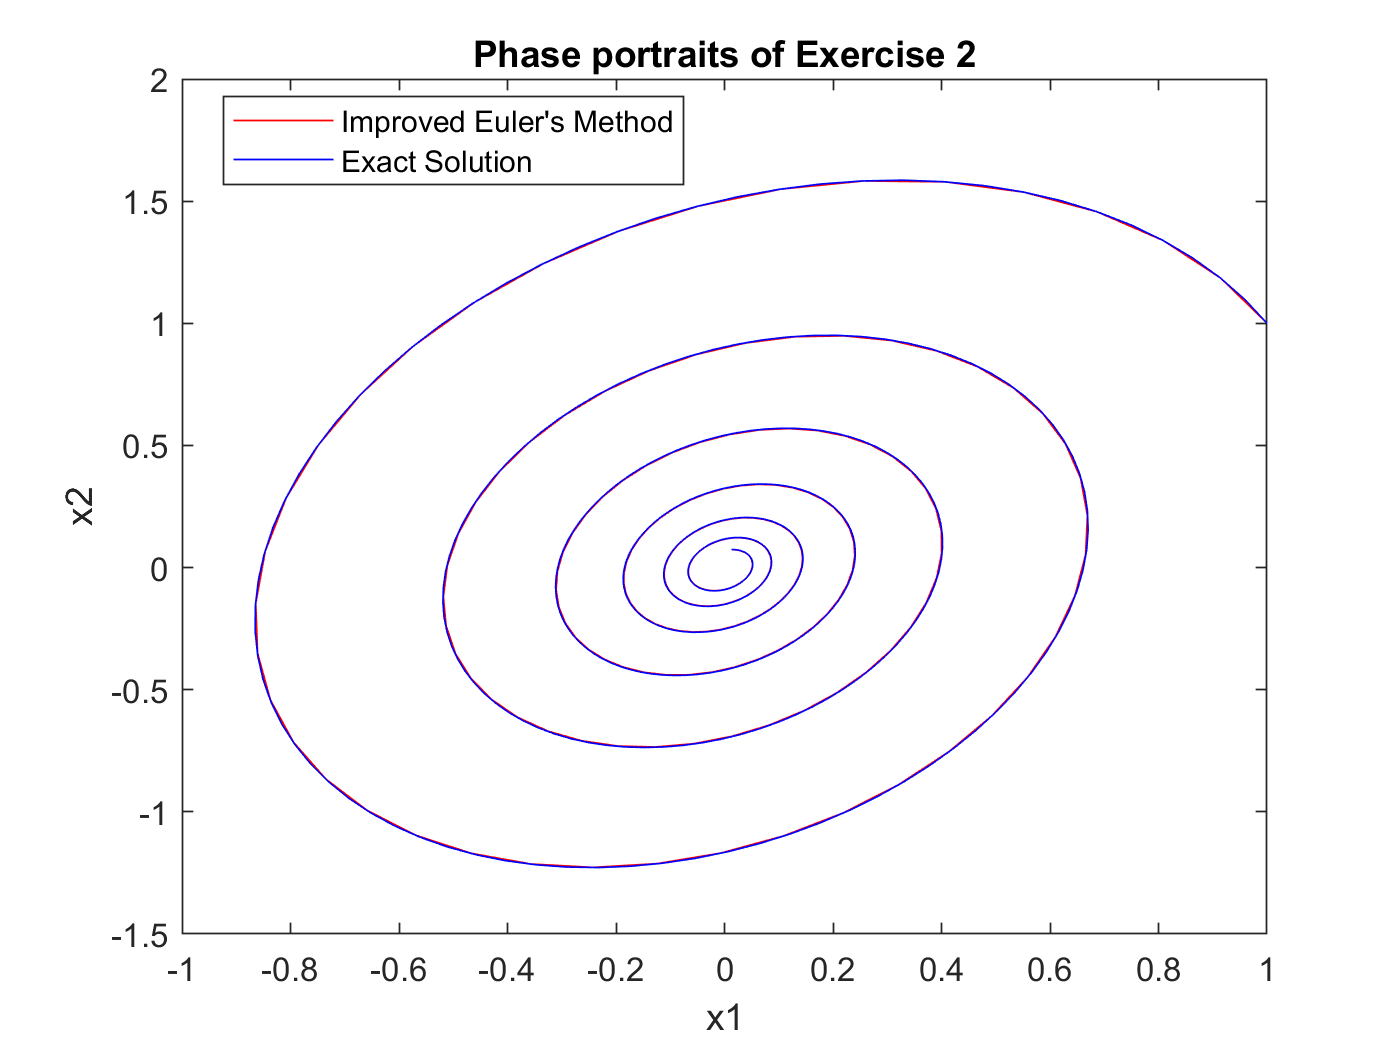

% Definition of inline functions
f = @(t,x1,x2) x1/2 - 2*x2;
g = @(t,x1,x2) 5*x1 - x2;

% Creation of vector x and input of the initial condition
x0 = 2:1;
x0(1,1) = 1;
x0(2,1) = 1;

% Definition of used parameters
h = 0.05;
t0 = 0;
tN = 4*pi;

% Heun/Improved Euler's Method
[T, X] = solvesystem_(f,g,t0,tN,x0,h);

% Definition of parameters used and the exact solution 
t = linspace(t0,tN,500);
x1_exact = exp(-t/4).*(3/20*cos(sqrt(151)*t/4)-(sqrt(151)/20)*sin(sqrt(151)*t/4)+(17/sqrt(151))*((sqrt(151)/20)*cos(sqrt(151)*t/4)+3/20*sin(sqrt(151)*t/4)));
x2_exact = exp(-t/4).*(cos(sqrt(151)*t/4)+(17/sqrt(151))*(sin(sqrt(151)*t/4)));

% The exact solution is:
% x1 = exp(-t/4).*(3/20*cos(sqrt(151)*t/4)-(sqrt(151)/20)*sin(sqrt(151)*t/4)+(17/sqrt(151))*((sqrt(151)/20)*cos(sqrt(151)*t/4)+3/20*sin(sqrt(151)*t/4)));
% x2 = exp(-t/4).*(cos(sqrt(151)*t/4)+(17/sqrt(151))*(sin(sqrt(151)*t/4)));

% Plotting the Phase portraits
plot(X(1,:),X(2,:),'r', x1_exact,x2_exact,'b');
ylabel('x2');
xlabel('x1');
title('Phase portraits of Exercise 2');
legend("Improved Euler's Method","Exact Solution",'Location','Best');

## Exercise 3

Objective: Compare your method with Euler's Method (from `iode`).

Details: Use `iode` to plot the solution for the same problem with the same step size as on Exercise 2.

Compare your solution on exercise 2, the exact solution from exercise 2 and the approximation using Euler's method. Plot the solution for Euler's method and make note of any differences.

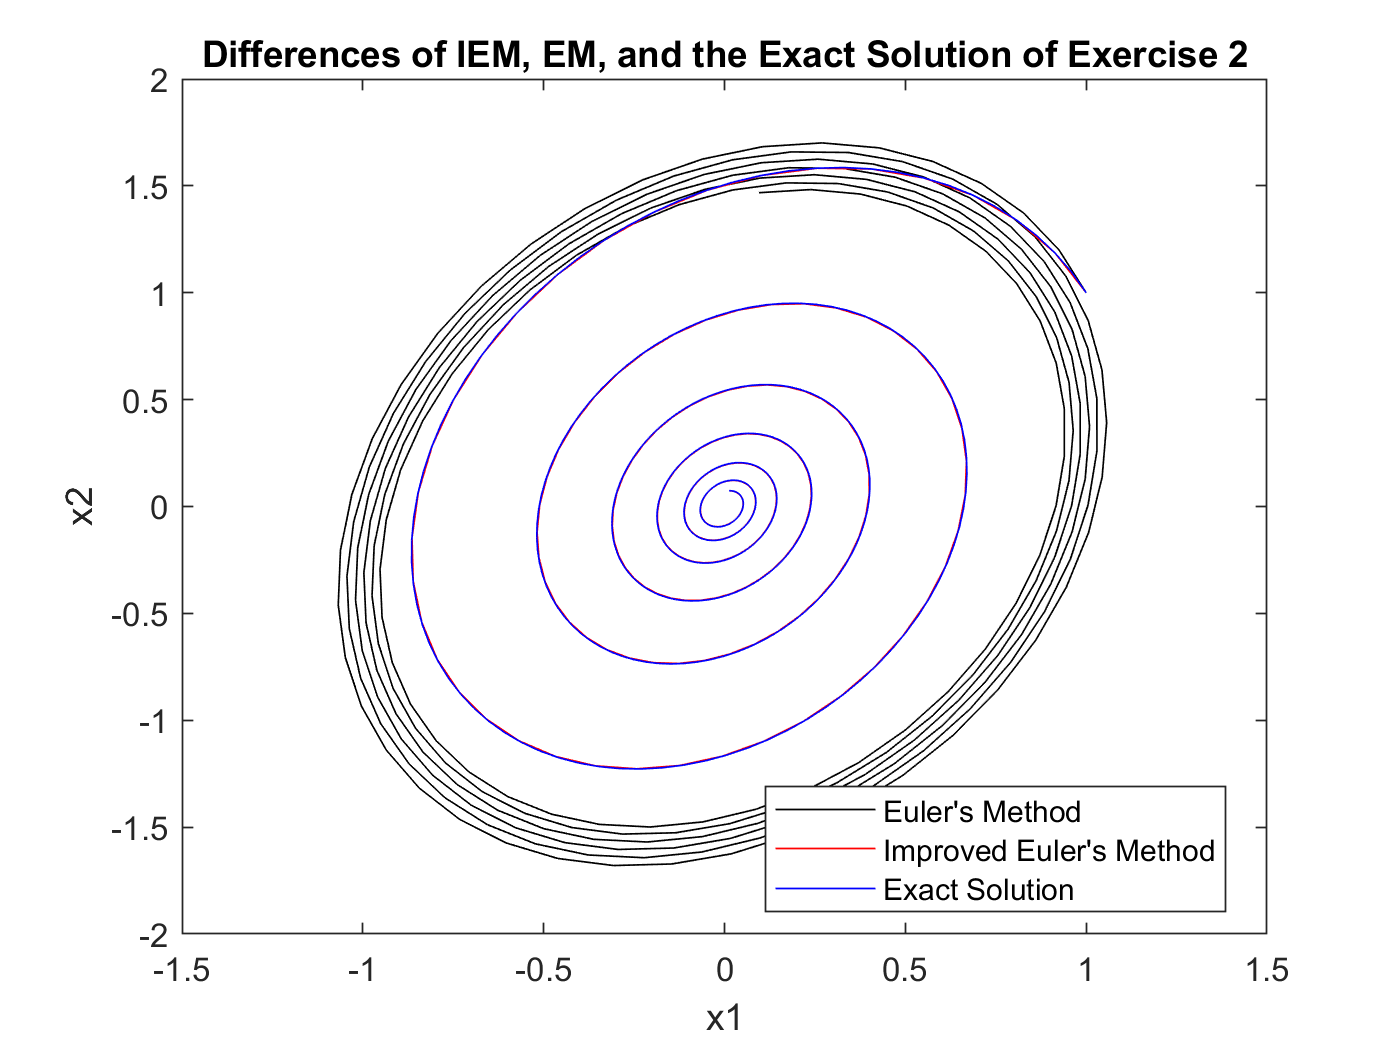

% Definition of the inline function that needs to be solved
% (Writing the system of equations as a vector)
f = @(t,x) [x(1)/2 - 2*x(2); 5*x(1) - x(2)]; 

% The initial condition
x0 = 2:1;
x0(1,1) = 1;
x0(2,1) = 1;

% Definition of the time vector for the Euler's Method
T_euler = linspace(0, 4*pi, 4*pi/0.05);

% Using the Euler's Method
X_euler = euler(f, x0, T_euler);

% Plotting and labeling the results
plot(X_euler(1,:),X_euler(2,:),'k',X(1,:),X(2,:),'r',x1_exact,x2_exact,'b');
xlabel('x1');
ylabel('x2');
title("Differences of IEM, EM, and the Exact Solution of Exercise 2");
legend("Euler's Method", "Improved Euler's Method", 'Exact Solution','Location','Best');


% Comparing to the Improved Euler's Method (IEM), the approximation that
% the Euler's Method (EM) gives is extremely poor. The most significant 
% difference is that the EM approximation spirals inward at a much lower 
% rate as opposed to both the exact solution and the IEM approximation.
% By the time that both the exact solution and the IEM approximation reach
% almost the centre of the ellipse, the EM approximation is only around 1/6
% of the ellipse.

## Saving Images in MATLAB

To do the following exercises, you will need to know how to output graphics from MATLAB. Create a folder on your Desktop (or elsewhere) to contain the files generated by these exercises. Make this folder the "Current Folder" in the left side of the main MATLAB window. This will ensure that the files output by MATLAB end up in the folder you created.

To save an image of a phase portrait, use the following steps:

1. Get the phase portrait looking the way you want in the `iode` window. 

2. Leaving `iode` open, switch to the main MATLAB window.

3. Type the command `print -dpng -r300 'filename.png'` in the command window.

This command will create a PNG graphic called `filename.png` in the current folder. The `-dpng` option tells MATLAB to output the graphic in PNG format; MATLAB also allows output in other formats, such as BMP, EPS, PNG and SVG. The `-r300` option tells MATLAB to set the resolution at 300 dots per inch and can be adjusted if you wish.

## Exercise 4

Objective: Analyze phase portraits.

Details: Compile the results of the following exercises into a single document (e.g. using a word processor) and export it to `PDF` for submission on Quercus. 

For each of the first-order systems of ODEs 4.1 to 4.10 below, do the following exercises:

(a) Generate a phase portrait for the system (centre the graph on the equilibrium point at (0,0)). Include a few trajectories.

(b) Classify the equilibrium on asymptotic stability, and behaviour (sink, source, saddle-point, spiral, center, proper node, improper node) - check table 3.5.1 and figure 3.5.7. Classify also as for clockwise or counterclockwise movement, when relevant.

(c) Compute the eigenvalues of the matrix (you do not need to show your calculations). Using the eigenvalues you computed, justify part (b).

To avoid numerical error, you should use Runge-Kutta solver with a step size of `0.05`. Change the display parameters, if necessary, to best understand the phase portrait.

4.1. `dx/dt = [2 1; 1 3] x` b) 1. Asymptotic Stability: Unstable 2. Behaviour: Nodal source 3. Clockwise or Counter-clockwise movement: N/A c) Eigenvalues of the matrix: (5+sqrt(5))/2 (5-sqrt(5))/2 Justification: Eigenvalues are real, positive, and unequal. Therefore, it is an unstable node (source).

4.2. `dx/dt = [-2 -1; -1 -3] x` b) 1. Asymptotic Stability: Asymptotically stable 2. Behaviour: Nodal sink 3. Clockwise or Counter-clockwise movement: N/A c) Eigenvalues of the matrix: (-5+sqrt(5))/2 (-5-sqrt(5))/2 Justification: Eigenvalues are real, negative, and unequal. Therefore, it is a stable node (sink).

4.3. `dx/dt = [-4 -6; 3 5] x` b) 1. Asymptotic Stability: Unstable 2. Behaviour: Saddle point 3. Clockwise or Counter-clockwise movement: N/A c) Eigenvalues of the matrix: -1 2 Justification: Both eigenvalues are real and unequal. One of the eigenvalues is positive and the other one is negative. Therefore, it is an unstable saddle point.

4.4. `dx/dt = [4 6; -3 -5] x` b) 1. Asymptotic Stability: Unstable 2. Behaviour: Saddle point 3. Clockwise or Counter-clockwise movement: N/A c) Eigenvalues of the matrix: 1 -2 Justification: Both eigenvalues are real and unequal. One of the eigenvalues is positive and the other one is negative. Therefore, it is an unstable saddle point.

4.5. `dx/dt = [0 -1; 1 -1] x` b) 1. Asymptotic Stability: Asymptotically stable 2. Behaviour: Spiral point 3. Clockwise or Counter-clockwise movement: Counter-clockwise c) Eigenvalues of the matrix: -1/2+isqrt(3)/2 -1/2-isqrt(3)/2 Justification: Both eigenvalues are complex, with negative real parts. Therefore, it is inward, stable spiral point.

4.6. `dx/dt = [0 1; -1 1] x` b) 1. Asymptotic Stability: Unstable 2. Behaviour: Spiral point 3. Clockwise or Counter-clockwise movement: Clockwise c) Eigenvalues of the matrix: 1/2+isqrt(3)/2 1/2-isqrt(3)/2 Justification: Both eigenvalues are complex, with positive real parts. Therefore, it is outward, unstable spiral point.

4.7. `dx/dt = [2 8; -1 -2] x` b) 1. Asymptotic Stability: Stable 2. Behaviour: Center 3. Clockwise or Counter-clockwise movement: Clockwise c) Eigenvalues of the matrix: 2i -2i Justification: Both eigenvalues are imaginary and have opposite signs. Therefore, it is a stable center.

4.8. `dx/dt = [-2 -8; 1 2] x` b) 1. Asymptotic Stability: Stable 2. Behaviour: Center 3. Clockwise or Counter-clockwise movement: Counter-clockwise c) Eigenvalues of the matrix: 2i -2i Justification: Both eigenvalues are imaginary and have opposite signs. Therefore, it is a stable center.

4.9. `dx/dt = [-8 5; -13 8] x` b) 1. Asymptotic Stability: Stable 2. Behaviour: Center 3. Clockwise or Counter-clockwise movement: Clockwise c) Eigenvalues of the matrix: i -i Justification: Both eigenvalues are imaginary and have opposite signs. Therefore, it is a stable center.

4.10. `dx/dt = [8 -5; 13 -8] x` b) 1. Asymptotic Stability: Stable 2. Behaviour: Center 3. Clockwise or Counter-clockwise movement: Counter-clockwise c) Eigenvalues of the matrix: i -i Justification: Both eigenvalues are imaginary and have opposite signs. Therefore, it is a stable center.